# Lab 1

## Prepare

Please go through the live scripts: MatlabReview and BasicAudioImage.

## Q1. Sine Wave

Create a cosine wave with a frequency of 1 kHz, sampled at 48 kHz, with a duration of 0.5 seconds and 0 phase offset. Play the sine wave and listen to check that it is correct. Plot the first three periods of your cosine signal with the correct time axis. Label your plot and label the axes.

**Solution**

## Q2. Periodic Signals

The complex exponential sequence $e^{j\,\omega_0\,n}$ or the sinusoidal sequence $\cos(\omega_0\,n)$are periodic if the normalized frequency $f_0=\frac{\omega_0}{2\pi}$ is a rational number; that is $f_0 = \frac{K}{N}$, where K and N are integers.

- Prove the result (write your answer using Latex math style)

- Generate exp(j0.1$\pi$n), -100 < n < 100. Plot its real and imaginary parts using the stem function. Is this sequence periodic? If it is, what is the fundamental period? From the examination of the plot, what interpretation can you give to the integers K and N?

- Generate and plot cos(0.1n), 0 < n < 63. Is this sequence periodic? Plot the sequence for 63 < n < 126. Plot the difference between these two regions of the sequence

## Solution

1.

2.

3.

## Q3. Convolution

Write a MATLAB program that explicitly computes the convolution $y = x[n] * h[n]$of the following two sequences: x[n], h[n] (given below). Your program should employ a for loop and use the sigfold, sigshift, sigmult functions.

What is the value of y[4] ?

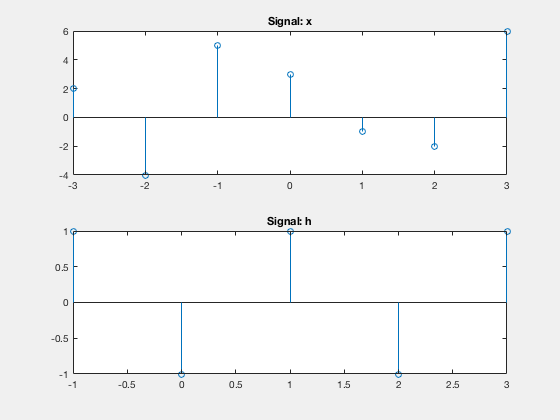

close all
nx = (-3:3) ;
x = [2,-4,5,3,-1,-2,6] ;
nh = (-1:3) ;
h = [1,-1,1,-1,1] ;
figure
set(gcf,'Visible','On')
subplot(2,1,1)
stem(nx,x)
title('Signal: x')
subplot(2,1,2)
stem(nh,h)
title('Signal: h')

## Solution

## Q4. Convolution as a Matrix-Vector Operation

When sequences x[n] and h[n] are of finite duration, then their linear convolution y[n] = x[n] * h[n] can be implemented using matrix-vector multiplication. In this case, we let y[n] and x[n] be column vectors and we have:


$$y = \mathbf{H}\,x$$


where linear shifts in h[n-k] are arranged as rows in the matrix **H**. The matrix **H** has an interesting structure and is called a Toeplitz matrix.

To investigate these issues do the following:

- Let x[n] = {1,2,3,4,5} for n = {0,1,2,3,4} and h[n] = {6,7,8,9} for n = {0,1,2,3}. Determine the linear convolution, y[n], of these two sequences. You can use the conv_m function.

- Express x[n] as a column vector; y[n] as a column vector. Determine the matrix **H**..

- Characterize the matrix **H**.

- Describe the first column and first row of **H**.

- Complete the MATLAB function conv_tp.m Use the MATLAB function toeplitz.

## Solution

1.

2.

3.

4.

5.